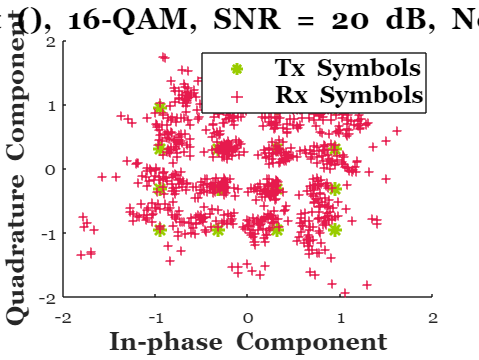

%% OFDM communication link (for different IEEE 802.11a standards)

% Let us define some constants that decide the colours used in the graphs:
txSymbolsColour = [0.6 0.8 0];
rxSymbolsColour1 = [0.6 0.2 1];
rxSymbolsColour2 = [0.9 0.1 0.3];

% Some boolean variables so that we can control what graphs get generated:
% Constellation 1: this is the chart corresponding to when no equalisation
% is used:
plotConstellation1 = true;
% Constellation 2: this is the chart corresponding to when equalisation is
% used:
plotConstellation2 = true;
% Boolean variable to plot the graphs illustrating the effect of the cylic
% prefix:
plotCPchart = true;

% Boolean variable to decide whether to plot the graph that illustrates
% what can happen when the cyclic prefix lenght is smaller than the channel
% delay:
plotCPlenVsChannelDelay = true;

% Boolean variable to control whether a channel with a long memory or
% maximum delay is used:
useLongDelayChannel = true;

% Boolean variable to control whether cyclic prefix is used or not:
useCP = false;

IEEEstandard = "802.11a"; % the IEEE standard that we want to simulate...

% Let us define the OFDM system parameters based on the IEEE 802 standard
% in use:
subcarrierSpacing = 312.5e3; % subcarrier spacing for 802.11a
Tu = 1/subcarrierSpacing; % the "useful" symbol period
G = 1/4; % the guard interval fraction
Tg = G*Tu; % the guard interval time
To = Tu + Tg; % the OFDM symbol duration (period)
fC = 5.5e9; % 802.11a uses the 5 GHz band
N = 52; % 48 for data, and 4 pilot tones
numPilotTones = 4; % no. pilot tones used 

% No. OFDM symbols in frame or "burst"
M = 32;

% Info. on modulation scheme being used:
modType = "QAM";
modOrder = 16;
bitsPerSymbol = log2(modOrder); % no. bits per complex symbol

% Channel information:
h = [0.96; 0.21; 0.15]; % channel coefficients...
if (useLongDelayChannel)
    % by making the channel long, we can show what happens when the maximum
    % delay of the channel is greater than the cylic prefix:
    h = [h; 0.1*rand(8, 1)];
end

if (useCP == true)
    cpLen = G*N;
else
    cpLen = 0;
end
    
% Generate bit stream. We are no modelling the encoding stage  in this
% program:
numBits = (N/2 - 1)*bitsPerSymbol*M;
txBits = randi([0 1], numBits, 1); % the bit stream

% Modulating stage (map bits to complex symbols):
switch(modType)
    case "QAM"
        modulatedData = qammod(txBits, modOrder, "InputType", "bit", "UnitAveragePower", true);     
    otherwise
        disp("Check the status of 'modType' above.")
        return % exit the program early
end

Ftx = zeros(N, M); % empty transmit frame

% Loading the data into the frame:
Ftx(2:N/2, :) = reshape(modulatedData, N/2-1, M);

% Impose Hermitian symmetry before the IFFT block:
Ftx(N/2+2:end, :) = conj(flip(Ftx(2:N/2, :), 1));

% Pass through IFFT block:
ofdmSymbols = ifft(Ftx);

% Add the cyclic prefix:
s = [ofdmSymbols(end-cpLen+1:end, :); ofdmSymbols];

% Pass through the channel. This involves the convolution between the
% channel - which is being modelled by a linear filter (h) - and the signal
% (s):
r = zeros(size(s, 1)+length(h)-1, M);
r_noise = zeros(size(s, 1)+length(h)-1, M);

SNRdB = 20; % channel SNR in dB

for j = 1:M
    r(:, j) = conv(h, s(:, j));
    r_noise(:, j) = awgn(r(:, j), SNRdB, "measured"); % create the noisy signal
end

% Remove the cyclic prefix and the tail caused by the channel delay spread.
% We should do this for each of the "M" OFDM symbols:
r_noise = r_noise(cpLen+1:end, :);
r_noise = r_noise(1:end-(length(h) - 1), :);

% Get the received frame:
Frx = fft(r_noise);

% Equalisation stage. First we get the channel response.
channelResponse = fft([h; zeros(N-length(h), 1)]);
% Now we perform the equalisation:
R = Frx./channelResponse;

R = R(2:N/2, :); % get the payload data

if (plotConstellation1 == true)
    figure(1)
    Frx = Frx(2:N/2, :);
    Frx = Frx(:);
    % Let us plot the constellation:
    scatter(real(modulatedData), imag(modulatedData), [50], txSymbolsColour, 'Marker', '*', 'LineWidth', 1.5);
    title("\bf\fontname{Georgia}\fontsize{14}Constellation Chart " + "("  + "), " + modOrder + "-" + modType + ", SNR = " + SNRdB + " dB, No equalisation at Rx");
    ylabel('\bf\fontname{Georgia}\fontsize{12}Quadrature Component');
    xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
    set(gca,'Fontname', 'Georgia');
    hold on
    scatter(real(Frx(:)), imag(Frx(:)), [20], rxSymbolsColour2, 'Marker', '+', 'LineWidth', 0.8);
    legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');
    hold off
end

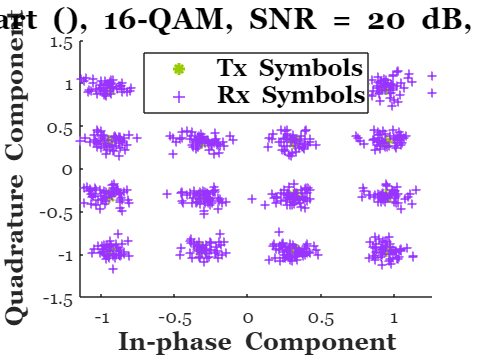


if (plotConstellation2 == true)
    figure(2)
    % Let us plot the constellation:
    scatter(real(modulatedData), imag(modulatedData), [50], txSymbolsColour, 'Marker', '*', 'LineWidth', 1.5);
    title("\bf\fontname{Georgia}\fontsize{14}Constellation Chart " + "(" + "), " + modOrder + "-" + modType + ", SNR = " + SNRdB + " dB, Equalisation at Rx");
    ylabel('\bf\fontname{Georgia}\fontsize{12}Quadrature Component');
    xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
    set(gca,'Fontname', 'Georgia');
    hold on
    scatter(real(R(:)), imag(R(:)), [20], rxSymbolsColour1, 'Marker', '+', 'LineWidth', 0.8);
    legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');
    hold off
end

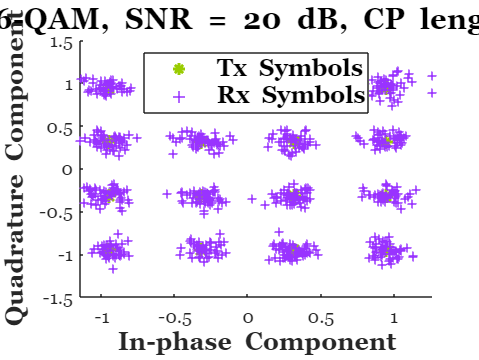


if (plotCPchart == true)
    figure(3)
    % Let us plot the constellation:
    scatter(real(modulatedData), imag(modulatedData), [50], txSymbolsColour, 'Marker', '*', 'LineWidth', 1.5);
    title("\bf\fontname{Georgia}\fontsize{14}Constellation Chart " + "(" + "), " + modOrder + "-" + modType + ", SNR = " + SNRdB + " dB, CP length = " + cpLen + ", Equalisation at Rx");
    ylabel('\bf\fontname{Georgia}\fontsize{12}Quadrature Component');
    xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
    set(gca,'Fontname', 'Georgia');
    hold on
    scatter(real(R(:)), imag(R(:)), [20], rxSymbolsColour1, 'Marker', '+', 'LineWidth', 0.8);
    legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');
    hold off
end

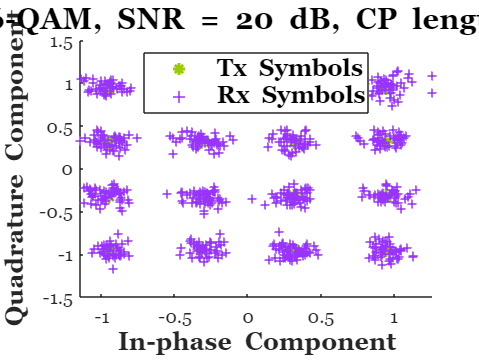


if (plotCPlenVsChannelDelay == true)
    figure(4)
    % Let us plot the constellation:
    scatter(real(modulatedData), imag(modulatedData), [50], txSymbolsColour, 'Marker', '*', 'LineWidth', 1.5);
    title("\bf\fontname{Georgia}\fontsize{14}Constellation Chart " + "(" + "), " + modOrder + "-" + modType + ", SNR = " + SNRdB + " dB, CP length = " + cpLen + ", Channel delay = " + (length(h)-1));
    ylabel('\bf\fontname{Georgia}\fontsize{12}Quadrature Component');
    xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
    set(gca,'Fontname', 'Georgia');
    hold on
    scatter(real(R(:)), imag(R(:)), [20], rxSymbolsColour1, 'Marker', '+', 'LineWidth', 0.8);
    legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');
    hold off
end